4. Considere 4 lançamentos de uma moeda equilibrada. Seja X a variável aleatória representativa do número de coroas observados nos 4 lançamentos.

a)

N = 1e5;
x = 0:4; %n de caras
A = zeros(1,N);

V = rand(4,N) > 0.5; %array de comprimento 4 com 0 e 1
for i = 1:N
    coroas = sum(V(1:4,i));
    A(i) = coroas;
end

%P_x -> x = n de coroas saídas
P_0 = sum(A(:) == 0) / N

P_0 = 0.0615

P_1 = sum(A(:) == 1) / N

P_1 = 0.2494

P_2 = sum(A(:) == 2) / N

P_2 = 0.3739

P_3 = sum(A(:) == 3) / N

P_3 = 0.2522

P_4 = sum(A(:) == 4) / N

P_4 = 0.0630

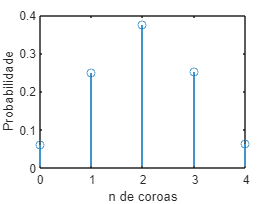


pX = [P_0 P_1 P_2 P_3 P_4];

stem(0:4,pX)
xlabel('n de coroas')
ylabel('Probabilidade')



%b)
E = sum(x .* pX) %valor esperado (média)

E = 2.0058

Var = sum((x - E).^2 .* pX) %variância

Var = 0.9995

std = sqrt(Var) %desvio padrão

std = 0.9998

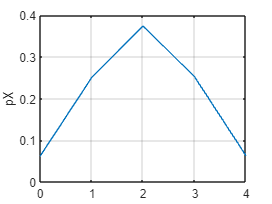



%c)
plot(x,pX) %quadrática
hold on


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( x, pX );

% Set up fittype and options.
ft = fittype( 'poly4' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );
fitresult;

% Plot fit with data.
%plot( fitresult, xData, yData );

ylabel('pX')
grid on
legend off
hold off




%d)
pX_teorico = zeros(1,5);
for i = 0:4
    pX_teorico(i+1) = prob_teorica(i,4,0.5); %(n de coroas, numero de moedas, chance de vir coroa)
end
fprintf("P0 = %f\nP1 = %f\nP2 = %f\nP3 = %f\nP4 = %f",pX_teorico(1:5))

P0 = 0.062500
P1 = 0.250000
P2 = 0.375000
P3 = 0.250000
P4 = 0.062500



%e)
E_teorico = sum(x .* pX_teorico) %valor esperado (média)

E_teorico = 2

Var_teorico = sum((x - E_teorico).^2 .* pX_teorico) %variância

Var_teorico = 1

std_teorico = sqrt(Var_teorico) %desvio padrão

std_teorico = 1



%f)
fprintf('i. P2 + P3 + P4 = %f', sum(pX_teorico((2:4)+1)))

i. P2 + P3 + P4 = 0.687500

fprintf('ii. P0 + P1 = %f', sum(pX_teorico((0:1)+1)))

ii. P0 + P1 = 0.312500

fprintf('iii. P1 + P2 + P3 = %f', sum(pX_teorico((1:3)+1)))

iii. P1 + P2 + P3 = 0.875000